# Plotting 

There are 4 main elements used to explore and visualise synaptic point clouds and analysis results:

- **Point clouds** : plot different groups of synapses as point clouds , representing each synapse as a point in 3D.

- **Voxels** : plot statistic per voxel (for example the number of gained synapses in a voxel, or the difference between the number of  lost and gained synapses)

- **DB-plane** : plot DB plane in 3D. 

- **Template** fish image : plot the image of the template fish to put everything else into the context.

This script shows how to plot all of these alements and combing them. For convenience, there are some helper functions at the end of the file, you can change them if you would like. 

*This script is using **stu**,**syn** and **db** prodused by the **ImportCohortData** and **CalculateDBPlane** scripts. 

## load utility functions

addpath('D:\Code\repos\synapse-redistribution\data_vizualization\utils');

## Plot Point Clouds

Here is an example how to plot a point cloud that consists only of gained synapses. You need to set the fish (or group of fish) for which to plot synapses. 

Here we are plotting the synapses of the first fish in the Learners group only: 

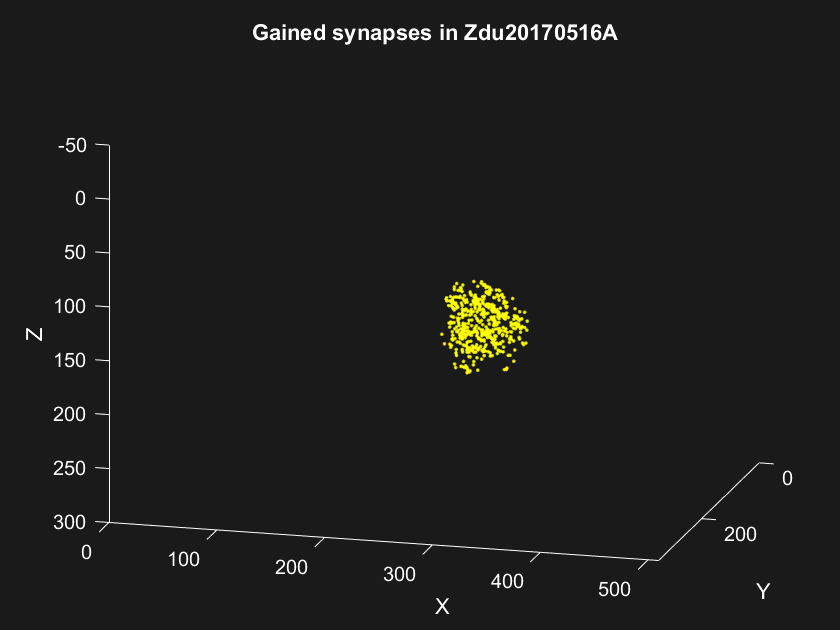

subject_id = stu.Id.Learners{1};
i_fish = stu.Learners(1);
% gained pointcloud 
pointCloud_ga = syn.gained.xyz_anat_mp{i_fish};
figure;
% plot point clouds of the lost and gained synapses
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);

title(['Gained synapses in ',subject_id],'Color',[1 1 1]);
axisProperties

And here for all the Learners : 

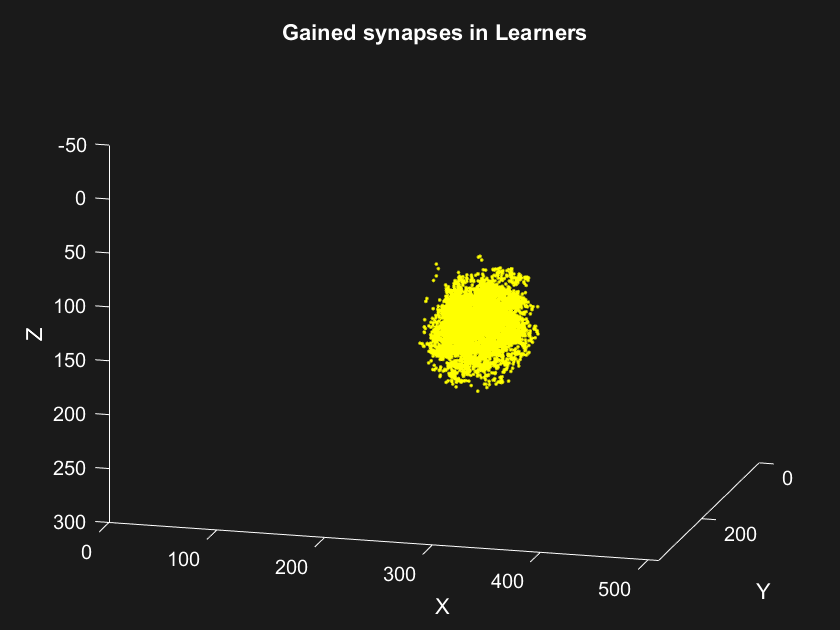

i_fish = stu.Learners;
% gained pointcloud 
pointCloud_ga = cat(1,syn.gained.xyz_anat_mp{i_fish});
figure;
% plot point clouds of the lost and gained synapses
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);

title(['Gained synapses in Learners'],'Color',[1 1 1]);
axisProperties

## Voxels

You can calculate any statistics per voxel and plot the areas where it satisfies some conditions. For example, here we are calculating the number of gained synapses per voxel ( in the first learner) and show ( using **plotPlainVoxel**) only those voxels where it is above 5. Also showing the corresponding point cloud for comparison.

**getVoxels** splits the space into the voxels of the given size (voxel_side) and, you need to provide a set of points in 3D (pointCloud_ga) and array of values that correspond to each of those points (I_synapse) . In this case I_synapse is equal to 1 for every point, serving as an indicator that there is a synapse. 

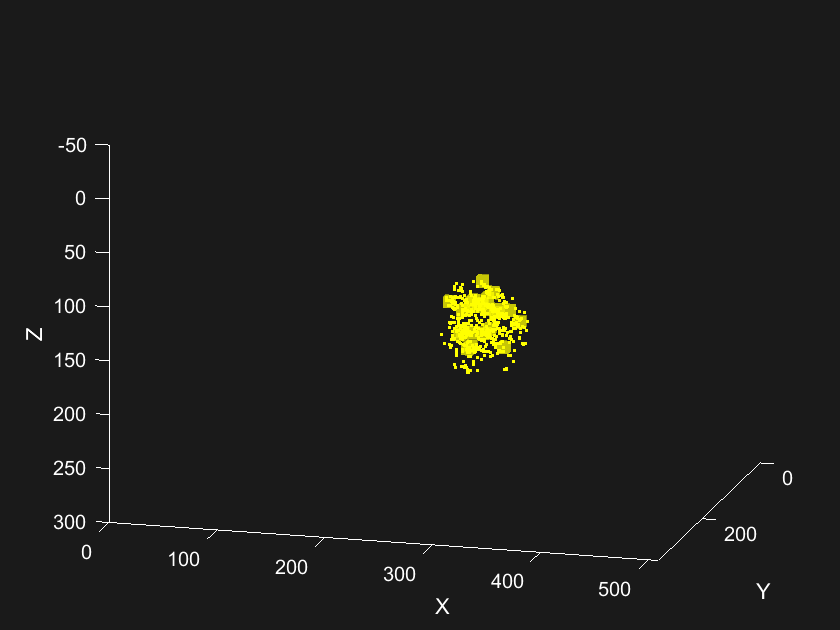

subject_id = stu.Id.Learners{1};
i_fish = stu.Learners(1);
% gained pointcloud 
pointCloud_ga = syn.gained.xyz_anat_mp{i_fish};

voxel_side = 10; % um
I_synapse = ones([length(pointCloud_ga),1]);
vox = getVoxels(voxel_side,pointCloud_ga,I_synapse);

figure;
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);
hold on
plotPlainVoxel(voxel_side,267,vox.voxel_data_sum,5,[1 1 0],0.5,[]);
hold on

axisProperties

Here is another example : now we will plot the difference between the number of lost and gained synapses per voxel in the same fish. And will only show areas where this difference is larger than 2 , using **plotPlain2Voxel** to plot voxels with 2 differnt colors.

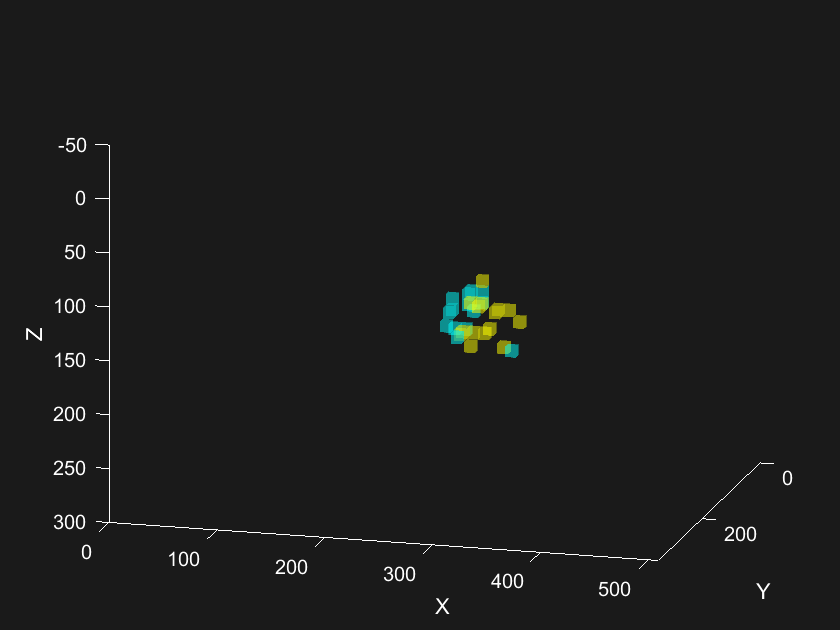


voxel_side = 10;
subject_id = stu.Id.Learners{1};
i_fish = stu.Learners(1);
% gained pointcloud 
pointCloud_ga = syn.gained.xyz_anat_mp{i_fish};
% lost pointcloud 
pointCloud_lo = syn.lost.xyz_anat_mp{i_fish};

% prepare getVoxels input
I_synapse = [ones([length(pointCloud_ga),1]);-ones([length(pointCloud_lo),1])];
xyz = [pointCloud_ga;pointCloud_lo];
% calculate the difference per voxel
vox_diff = getVoxels(voxel_side,xyz,I_synapse);
% split into gained and lost areas
vox_ga = vox_diff.voxel_data_sum.*(vox_diff.voxel_data_sum>0);
vox_lo = -vox_diff.voxel_data_sum.*(vox_diff.voxel_data_sum<0);

figure;
plotPlain2Voxel(voxel_side,267,vox_ga,5,vox_lo,5);

axisProperties

## Plot DB-plane

Choose the plane you want to plot. Here is the DB_plane based on the lost and gaines synapses for the first learner.

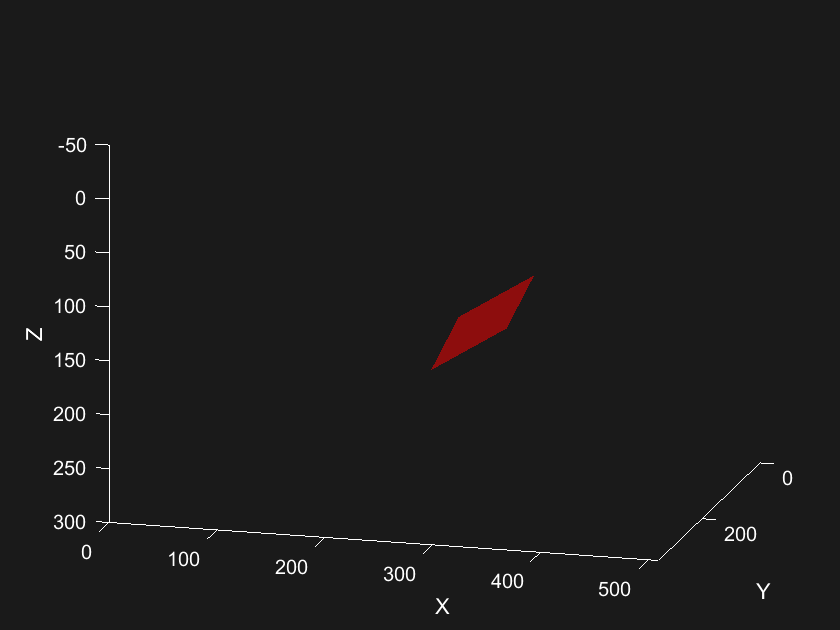

cl = db.Learners.number.cl{1};

figure;
plotDecisionBoundary([pointCloud_ga;pointCloud_lo],cl,'Color',[1 0 0],'FaceAlpha',0.5);
hold on

axisProperties

## Plot Template Image 

Load the template image to show in the background and specify the image resolution. All fish have been regestered to this template image. You can get the template image that was used in the study here : [https://www.dropbox.com/s/e7uw92llumm7hcu/TEMPLATE_ImgZfDsy20180223B3_ToYZPlane_bin221.tif?dl=0](https://www.dropbox.com/s/e7uw92llumm7hcu/TEMPLATE_ImgZfDsy20180223B3_ToYZPlane_bin221.tif?dl=0) 

imageFile = 'D:\TR01\RealData_All\Template\TEMPLATE_ImgZfDsy20180223B3_ToYZPlane_bin221.tif';
Img = read_tiff3d(imageFile,0,[],[]);
img_res = [0.52 0.52 0.4];

You can plot slices of the image in XY and XZ planes. Specify the depth of the slice (in microns) and plot it:

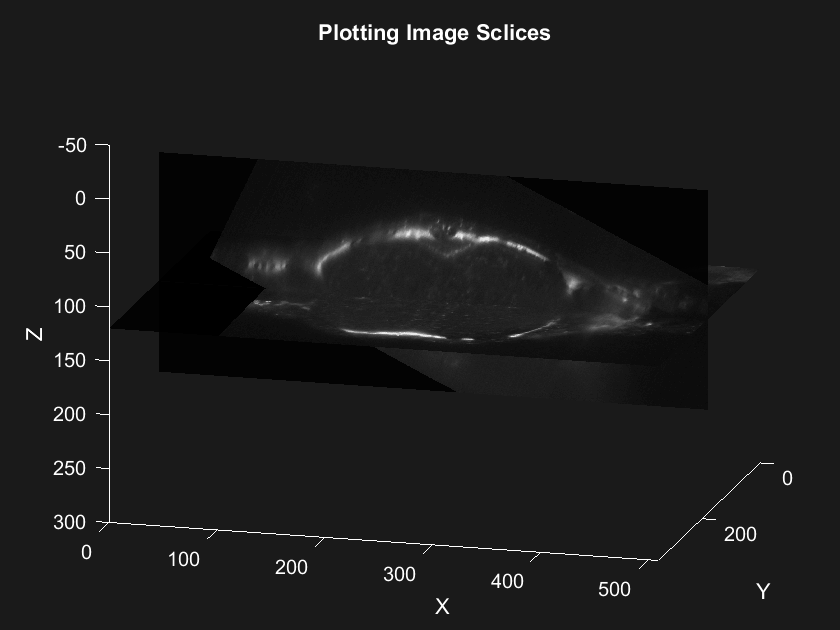

zSlice = 120; % um
ySlice = 180; % um

figure;
% plot two image slices (in xy and xz planes )
plotImageSlice(Img,img_res,"xy",zSlice);
hold on
plotImageSlice(Img,img_res,"xz",ySlice);

title('Plotting Image Sclices','Color',[1 1 1]);
axisProperties

## Putting it all together 

You can combine all these elements any way you want.

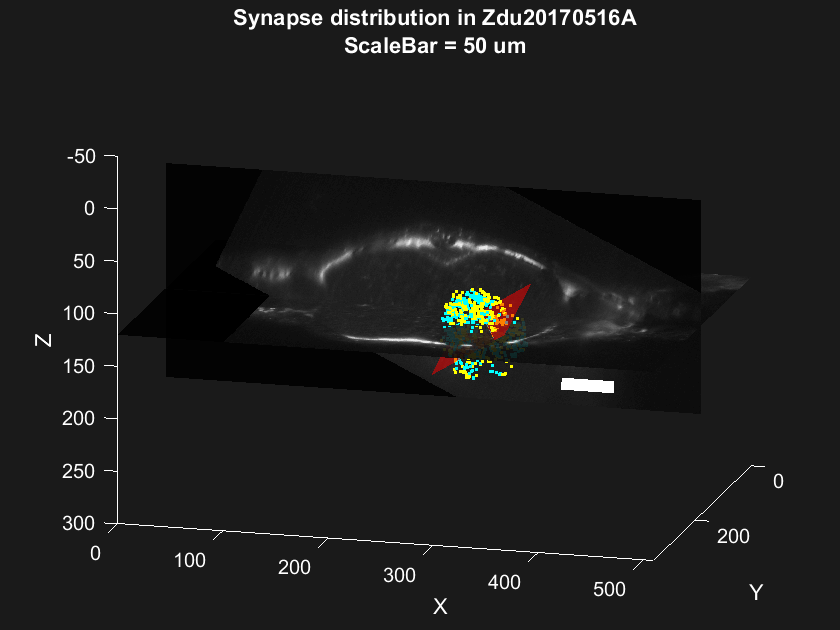

figure;
% plot two image slices (in xy and xz planes )
plotImageSlice(Img,img_res,"xy",zSlice);
hold on
plotImageSlice(Img,img_res,"xz",ySlice);
hold on
% plot point clouds of the lost and gained synapses
plot_ptc(pointCloud_lo,'Color',[0 1 1],'MarkerSize',5);
hold on
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);
hold on
% plot DB-plane
plotDecisionBoundary([pointCloud_ga;pointCloud_lo],cl,'Color',[1 0 0],'FaceAlpha',0.5);
hold on
% plot scale bar
plot_scalebar(50,[420,340,zSlice+20]);

title({['Synapse distribution in ',subject_id];['ScaleBar = ',num2str(sbWidth),' um']},'Color',[1 1 1]);

axisProperties

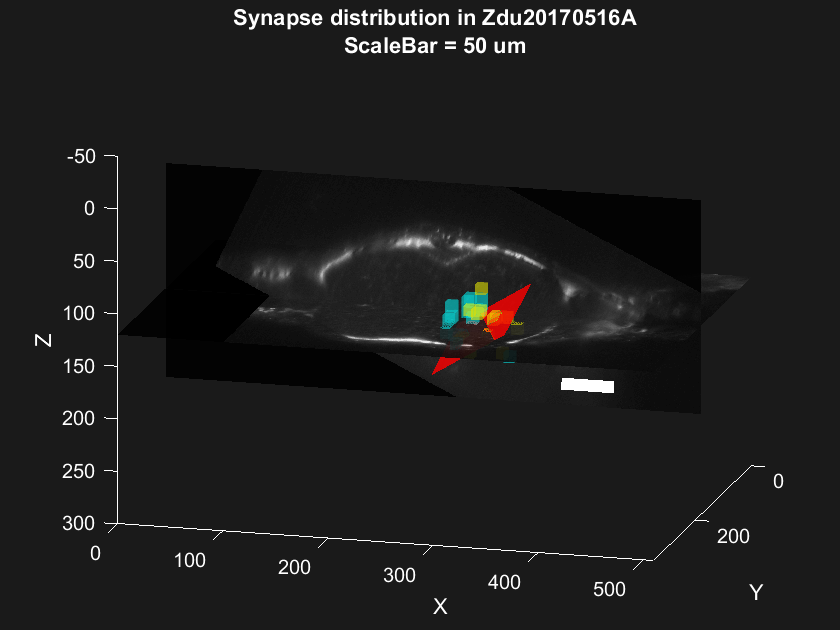

figure;
% plot two image slices (in xy and xz planes )
plotImageSlice(Img,img_res,"xy",zSlice);
hold on
plotImageSlice(Img,img_res,"xz",ySlice);
hold on
% plot point clouds of the lost and gained synapses
hold on
plotPlain2Voxel(voxel_side,267,vox_ga,5,vox_lo,5);
% plot DB-plane
plotDecisionBoundary([pointCloud_ga;pointCloud_lo],cl,'Color',[1 0 0],'FaceAlpha',0.8);
hold on
% plot scale bar
plot_scalebar(50,[420,340,zSlice+20]);

title({['Synapse distribution in ',subject_id];['ScaleBar = ',num2str(sbWidth),' um']},'Color',[1 1 1]);

axisProperties

## Helper functions 

These are two functions: one sets the axis properties and another one draws a scale bar. They are helpful to save space when plotting, feel free to change them to your liking.

function axisProperties
% sets the axis limits, direction, labels and figure colors and default view
    xAxisLim = [0 510];
    yAxisLim = [0 350];
    zAxisLim = [-50 300];
    
    daspect([1 1 1])
    set(gca,'Zdir','reverse')
    set(gca,'Xdir','reverse')
    
    set(gca,'color',[0.1 0.1 0.1])
    set(gcf,'color',[0.1 0.1 0.1])
    set(gca,'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1]);
    grid off
    box off
    
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
    
    xlim(xAxisLim);
    ylim(yAxisLim);
    zlim(zAxisLim);
    
    % rotate to dorsal view:
    %view(180,90);
    
    % arbitrary angle in 3D:
    view([-165 15])

end

function plot_scalebar(length,position)
% plots a scalebar of the given size (in microns) 
% at position (in 3D : x,y,z ,in microns)
    scaleBarX = position(1);
    sbWidth = length; 
    scaleBarY = position(2); 
    scaleBarZ = position(3); 
    
    plot3([scaleBarX,scaleBarX+sbWidth],[scaleBarY scaleBarY],[scaleBarZ scaleBarZ],...
        '-','Color',[1 1 1],'LineWidth',6);
end